clc
clear
close all

% Order of ideal function
N = 3

N = 3


% Number of microphones M > N 
%M = N +3
M =7

M = 7


% Steering of main lobe
steerAng =35.01

steerAng = 35.0100

%xs = cosd(steerAng);
xs = sind(steerAng-90);

% Speed of sound (m/s)
%c = 343;  
c = 1496;


% Minimum and maximum frequency
f_min = 0;
f_max = 24e3;

% Signal frequency to design filter (Hz)
f = f_max; % (Invariant)

% Frequency sweep list
freqs = linspace(f_min, f_max, (f_max-f_min)/(100)+1);
freqs(1) = 20;

thetas = linspace(0,2*pi,360);

% Length of array (m)
dmax = 1;


ULA1 = linspace(0, dmax, M)

ULA1 =          0    0.1667    0.3333    0.5000    0.6667    0.8333    1.0000


%ULA1 = (0:2).*0.6
ULA1Offset = ULA1;


micArray = sort(unique([ULA1]))

micArray =          0    0.1667    0.3333    0.5000    0.6667    0.8333    1.0000




%tauULA1 = (micArray([1 ceil(end/2) end])*xs)/c;
tauULA1 = (ULA1Offset*xs)/c;


%save('DASParams.mat', 'steerAng', 'micArray', 'tauULA1', 'tauULA2', 'tauULA3')


%dfIntegral = zeros(1,length(freqs));
dfalt = zeros(1,length(freqs));
output = zeros(length(freqs),length(thetas));
for b=1:length(freqs)
    %for q=1:length(thetas)
    outputEach = exp(-1i*2*pi*freqs(b)*(ULA1Offset.*cos(thetas(:))/c+tauULA1));
    dfNum = exp(-1i*2*pi*freqs(b)*(ULA1Offset.*xs/c+tauULA1));

    %end
    output(b,:) = sum(outputEach,2);
    

    % Approximate integral through trapezoidal
    dfPower = abs(power(output,2));
    dfIntegral = 0.5*(thetas(2)-thetas(1))*(dfPower(b,1)*sin(thetas(1)) + ...
        2*dfPower(b,2:end/2-1)*sin(thetas(2:end/2-1))' + dfPower(b,end/2)*sin(thetas(end/2)));
    dfalt(b) = 10*log10(power(sum(abs(dfNum)),2)/(0.5*dfIntegral));
    %dfalt(b) = 10*log10(power(abs(h'*(exp((-1i*2*pi*freqs(b)*d*(0:M-1).*xs)/c))'),2)/(0.5*dfIntegral(b))) ;
end

%bp = abs(output);
bp = sqrt(power(real(output),2)+power(imag(output),2))/M

bp =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9997    0.9997    0.9997    0.9997    0.9997    0.9997    0.9997    0.9997    0.9997    0.9997    0.9997    0.9997    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    

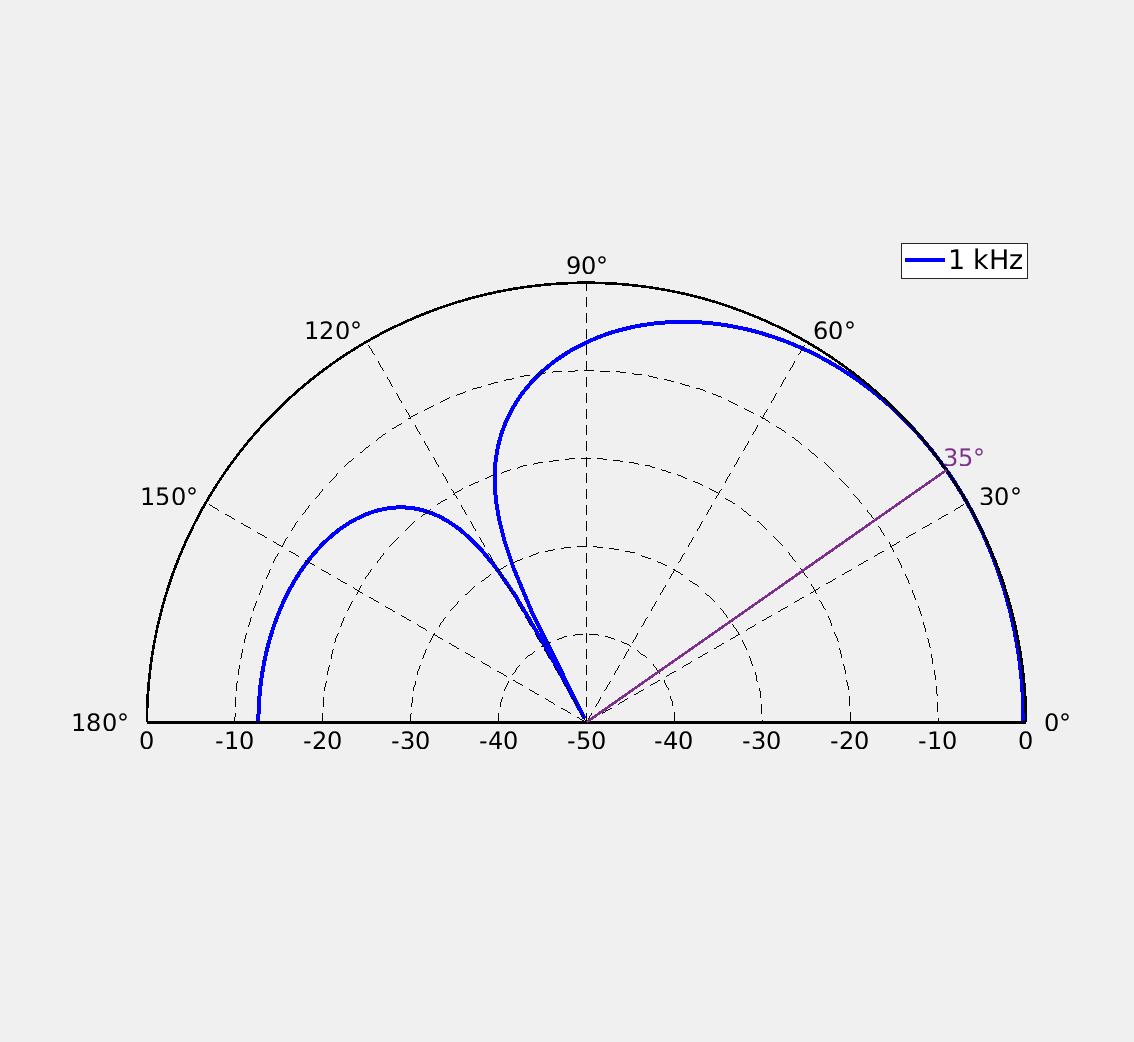

mindB = -50;
logOutput = mag2db(bp);
logOutput(logOutput < mindB) = mindB;

indexHz = find(freqs==1000); % Find design frequency in sweep list
plotVisibility = 'on';

figure(1)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 20]) %21/2-2*2
circPlot(freqs(indexHz), thetas, logOutput(indexHz,:), steerAng)
exportgraphics(gcf,'DAS8MSingle.pdf')

figure(2)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 30])

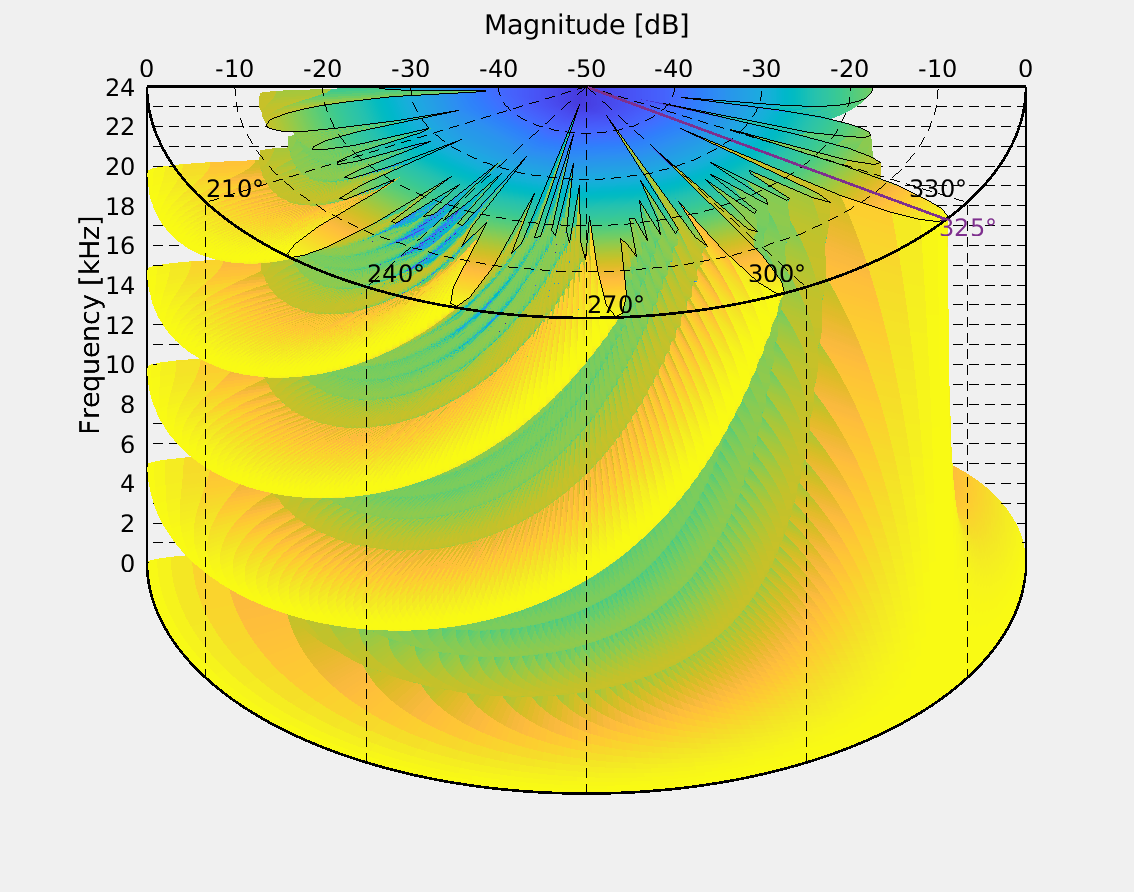

cylindricalPlot(freqs, thetas, logOutput, steerAng)
exportgraphics(gcf,'DAS8MBroad.pdf')

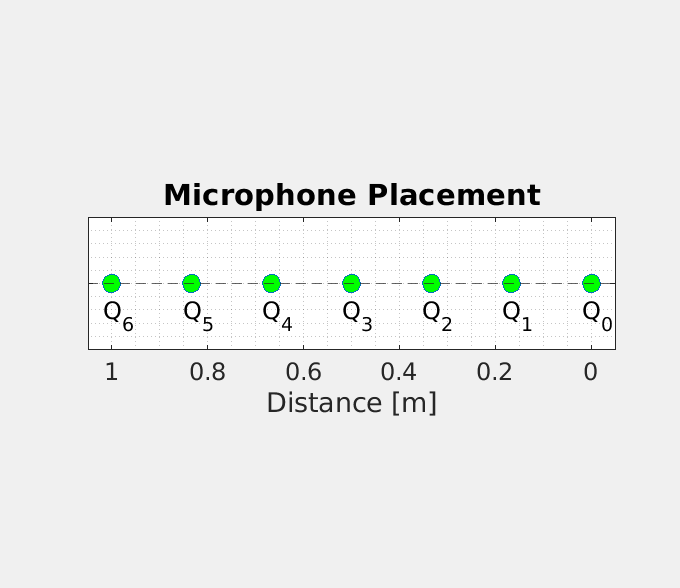

% figure(3)
% plot(micArray, zeros(length(micArray),1), 'o')
% hold on
% pbaspect([2 1 1])
% set(gca,'YTickLabel',{' '})
% grid minor
% hold off

figure(3)
plot(micArray, zeros(length(micArray),1), 'o', 'MarkerSize', 14, 'MarkerFaceColor', 'g')
hold on
yline(0, 'LineStyle', '--')
%plot(micArray, zeros(length(micArray),1), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'g')
%text(micArray, zeros(length(micArray),1)+0.5+(-1).^(0:length(micArray)-1)'*0.12, string(round(micArray,3)), 'HorizontalAlignment', 'center', 'FontSize', 12)
%text(micArray, zeros(length(micArray),1)+0.5+[0 -0.1 0.2 -0.1 0.2 -0.1 0]', flip(string(round(micArray,3))), 'HorizontalAlignment', 'center', 'FontSize', 18)
text(micArray+0.014, zeros(length(micArray),1)-0.5, 'Q_' + flip(string(0:length(micArray)-1)), 'HorizontalAlignment', 'center', 'FontSize', 18)
set(gca,'YTickLabel',{' '})
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])
xlim([-0.05 1.05])
pbaspect([4 1 1])
ax = gca;
ax.FontSize = 18;
xticks(0:0.2:1)
xticklabels(string(flip(0:0.2:1)))
xlabel('Distance [m]', 'FontSize', 20)
title('Microphone Placement', 'FontSize', 22)
grid minor
hold off
exportgraphics(gcf,'DAS8MMicArray.pdf')


figure(4)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])

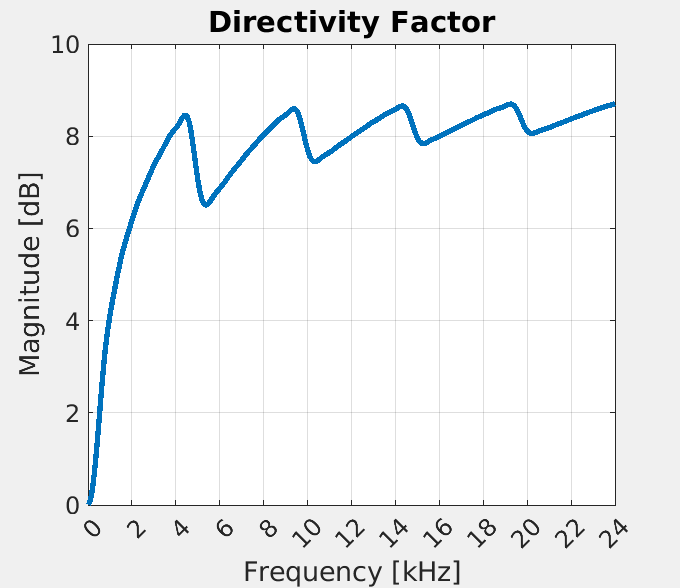

plot(freqs, dfalt, 'LineWidth', 4)
hold on
xlim([0 f_max])
ylim([0 10])
ytickList = linspace(0,10,10+1);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(f_min,f_max,f_max/1000+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Magnitude [dB]', 'FontSize', 20)
title('Directivity Factor', 'FontSize', 22)
grid
%legend('M=' + string(Mlist), 'Location', 'northwest')
hold off
exportgraphics(gcf,'DAS8MDF.pdf')